%clear;clc;
V=1;
position=[0 0 0;0 0 0];
velocity=[0 0 0;0 0 0];
mass=1;
I=[1 1 1];
delta_t=1;

s=Submarine(V,mass,I,position,velocity,delta_t);

s.velocity;
f=[0 1 0;0 0 0];
s.Force(f);
s.velocity;

p=[];
for i=1:2000
    s.update_position();
    p=[p;s.position(1,:)];
end
% plot3(p(:,1),p(:,2),p(:,3),'-b')
% grid on %加网格
% axis square %命令坐标为方形

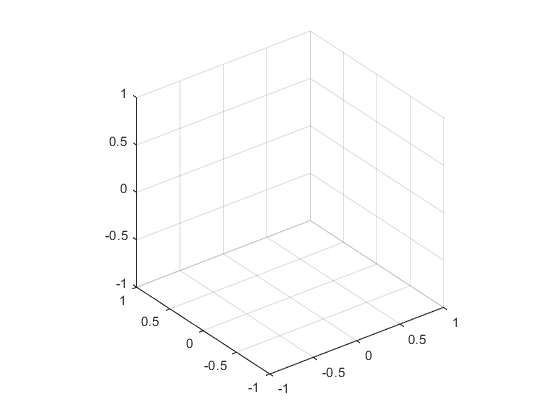

clear;clc;
V=1;
position=[0 0 0;0 0 0];
velocity=[0 0 0;0 0 0];
mass=1;
I=[1 1 1];
delta_t=1;
s=Submarine(V,mass,I,position,velocity,delta_t);

rho=1;e_velocity=[1 0 0];C=1;A=1;
e=environment(A,rho,e_velocity,0,C,0);
p=position;
v=velocity;
for i=1:20
    s.update_position();
    s.Force(get_force(s,e));
    p=[p;s.position(1,:)];
    v=[v;s.velocity(1,:)];
end
plot3(p(:,1),p(:,2),p(:,3),'-b')
grid on %加网格
axis square %命令坐标为方形

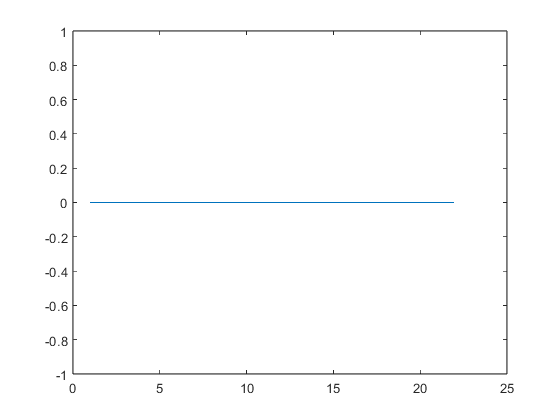

% figure(2)
% plot3(v(:,1),v(:,2),v(:,3),'-r')
% grid on %加网格
% axis square %命令坐标为方形
figure(3)
plot(p(:,3))